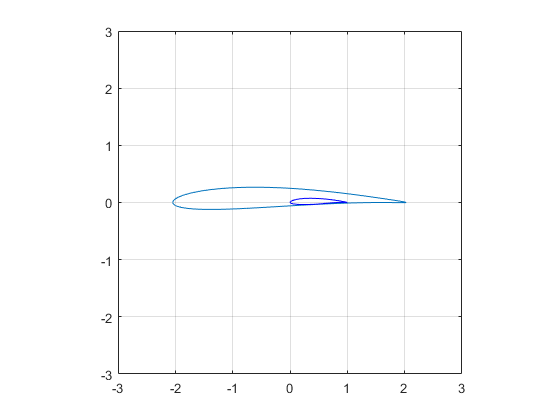

clc
clear

j = ["EPPLER 818 Hydrofoil", "NACA 63-412 Aifoil", "RG 8 Airfoil", "YS 930 Hydrofoil"]; %index hydrofoil names from sheets for ease
dataPos3 = readmatrix('suppFiles.xlsx','Sheet',j(3),'Range','A3:B34');
dataNeg3 = readmatrix('suppFiles.xlsx','Sheet',j(3),'Range','A35:B64');

r = 1.1;
s_x = -0.065;
s_y = 0.051;
s = s_x + 1i*s_y;
lambda = r - sqrt(s_x^2 + s_y^2);
angle = 0:.1:2*pi;
z_circle = r*(cos(angle)+1i*sin(angle)) + s;
z_airfoil = z_circle+lambda^2./z_circle;
plot(real(z_airfoil), imag(z_airfoil),dataPos3(:,1), dataPos3(:,2),'b',dataNeg3(:,1), dataNeg3(:,2),'b')
axis equal
axis([-3 3 -3 3])
grid on